Import fuzzy logic from fuzzy logic designer

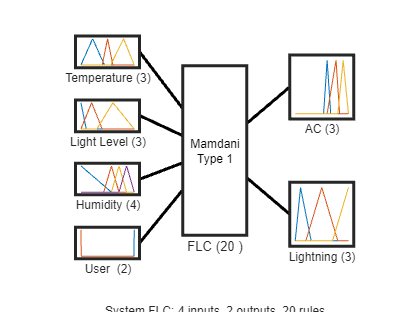

fis = readfis('FLC.fis');
plotfis(fis);

Example plots of some inputs

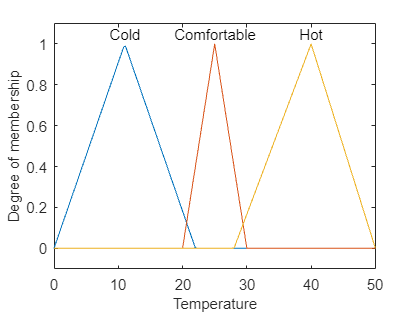

plotmf(fis,"input",1)

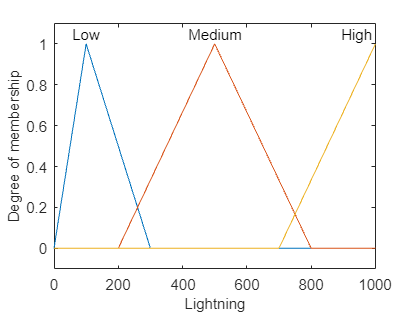

plotmf(fis,"output",2)

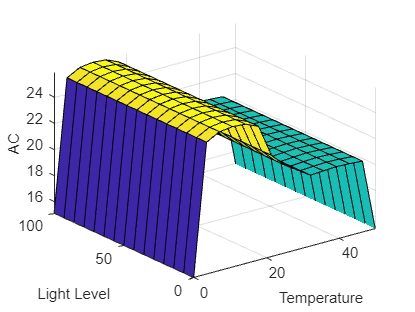

gensurf(fis)

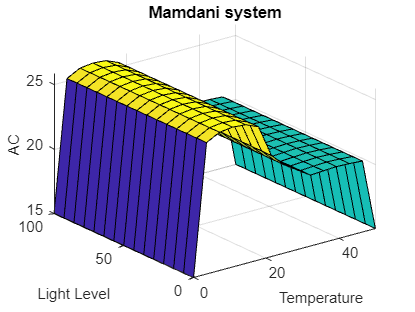

sug_fis = convertToSugeno(fis);
fis_struct = convertToStruct(fis);

gensurf(fis)
title('Mamdani system')

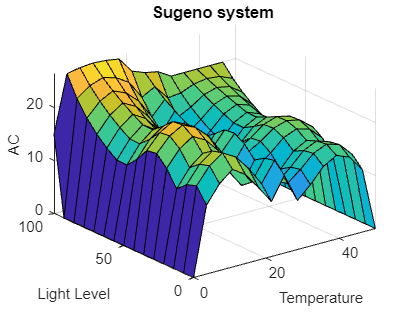

gensurf(sug_fis)
title('Sugeno system ')

Sample input to defuzzyfication and evaulation

% Define input values
sample_input = [50, 100, 70, 18];

[output,fuzzifiedIn,ruleOut,aggregatedOut,ruleFiring] = evalfis(fis,sample_input);

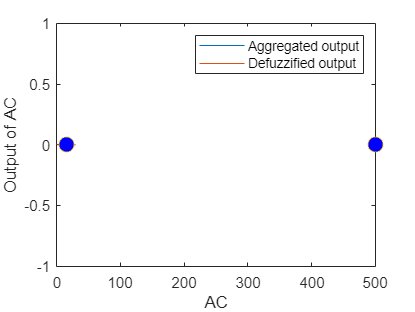


%Defuzzification of output 1
outputRange = linspace(fis.output(1).range(1),fis.output(1).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
hold off;
xlabel(fis.Outputs(1).Name);
ylabel('Output of '+fis.Outputs(1).Name);
legend('Aggregated output', 'Defuzzified output');

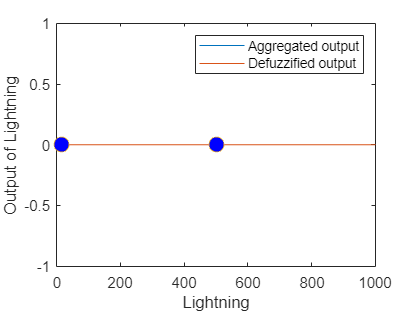


%Defuzzification of output 2
outputRange = linspace(fis.output(2).range(1),fis.output(2).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
hold off;
xlabel(fis.Outputs(2).Name);
ylabel('Output of '+fis.Outputs(2).Name);
legend('Aggregated output', 'Defuzzified output');